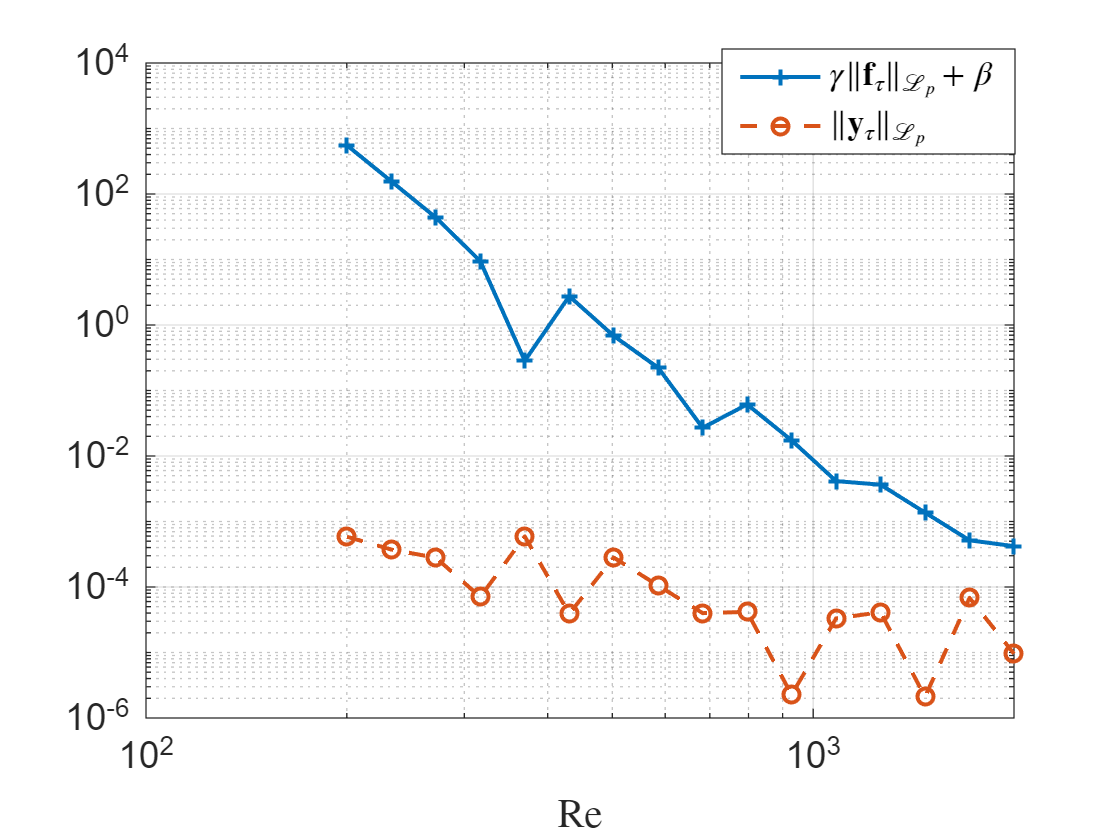

% Plot 1: Re_list vs Gap
colors = lines(16);
line_styles = ["-","--","-.",":"];
markers = {'+', 'o', '*', 'x', 's', 'd', '^', 'v', '>', '<', 'p', 'h'};
line_width = 1.5;
% Preallocate arrays to store results
Gamma_theorem_last = NaN(size(Gamma_theorem, 1), 1); % Last non-NaN values
ind_Gamma_theorem_last = NaN(size(Gamma_theorem, 1), 1); % Indices of last non-NaN values

% Loop over each row (ind_Re)
for ind_Re = 1:size(Gamma_theorem, 1)
    row_data = Gamma_theorem(ind_Re, :);
    
    % Find non-NaN indices in the row
    non_nan_indices = find(~isnan(row_data));
    
    if ~isempty(non_nan_indices)
        % Get the last non-NaN index and value
        ind_last_non_nan = non_nan_indices(end);
        Gamma_theorem_last(ind_Re) = row_data(ind_last_non_nan);
        ind_Gamma_theorem_last(ind_Re) = ind_last_non_nan;
    else
        % If all values are NaN, keep as NaN
        Gamma_theorem_last(ind_Re) = NaN;
        ind_Gamma_theorem_last(ind_Re) = NaN;
    end
end

figure;
% loglog(Re_list, u_tau_Lp(:, 1), line_styles{1}, 'LineWidth', line_width, 'Color', colors(1, :));
h1 = loglog(Re_list, Gamma_theorem_last(16,:).*u_tau_Lp(:,16) + beta_theorem_p(:,16), line_styles{1}, 'LineWidth', line_width, 'Color', colors(1, :), 'Marker', markers{1});
hold on;
% h2 = loglog(Re_list, Gamma_theorem_min(:,16).*u_tau_Lp(:,16) + beta_theorem_p(:,16), line_styles{3}, 'LineWidth', line_width, 'Color', colors(3, :), 'Marker', markers{3});
h3 = loglog(Re_list, y_tau_Lp(:, 16), line_styles{2}, 'LineWidth', line_width, 'Color', colors(2, :),'Marker', markers{2});
hold off;
xlim([1e2, 2000]);  
xlabel('Re', 'FontSize', 12, 'Interpreter', 'latex');
legend([h1, h3], {...
    ['$\gamma \|\mathbf{f}_{\tau}\|_{\mathcal{L}_p} + \beta$'], ...
    ['$\|\mathbf{y}_{\tau}\|_{\mathcal{L}_p}$']}, ...
    'Interpreter', 'latex');
grid on;
set(gca, 'FontSize', 14);

hold off;

legend("Position",[0.64503,0.83306,0.26113,0.093])

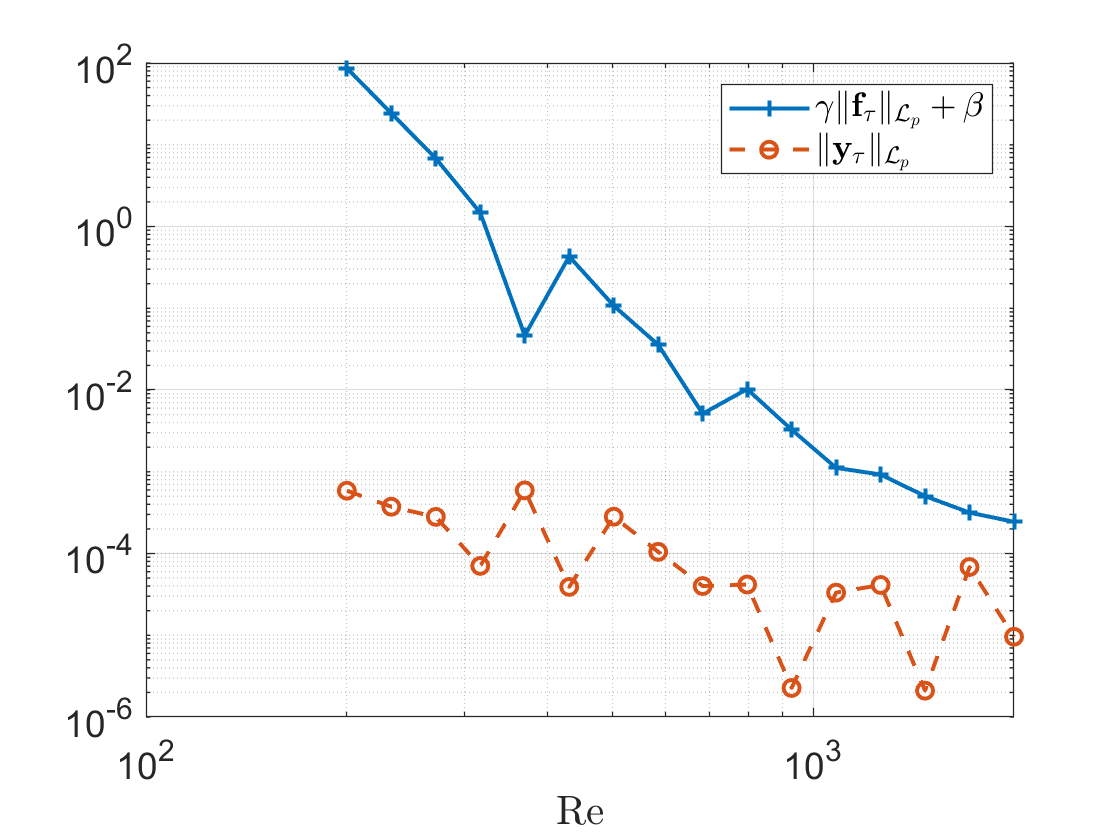


figure;
% loglog(Re_list, u_tau_Lp(:, 1), line_styles{1}, 'LineWidth', line_width, 'Color', colors(1, :));
h1 = loglog(Re_list, Gamma_theorem_last(12,:).*u_tau_Lp(:,12) + beta_theorem_p(:,12), line_styles{1}, 'LineWidth', line_width, 'Color', colors(1, :), 'Marker', markers{1});
hold on;
% h2 = loglog(Re_list, Gamma_theorem_min(:,12).*u_tau_Lp(:,12) + beta_theorem_p(:,12), line_styles{3}, 'LineWidth', line_width, 'Color', colors(3, :), 'Marker', markers{3});
h3 = loglog(Re_list, y_tau_Lp(:, 12), line_styles{2}, 'LineWidth', line_width, 'Color', colors(2, :),'Marker', markers{2});
hold off;
xlim([1e2, 2000]);  
xlabel('Re', 'FontSize', 12, 'Interpreter', 'latex');
legend([h1, h3], {...
    ['$\gamma \|\mathbf{f}_{\tau}\|_{\mathcal{L}_p} + \beta$'], ...
    ['$\|\mathbf{y}_{\tau}\|_{\mathcal{L}_p}$']}, ...
    'Interpreter', 'latex');
grid on;
set(gca, 'FontSize', 14);

hold off;

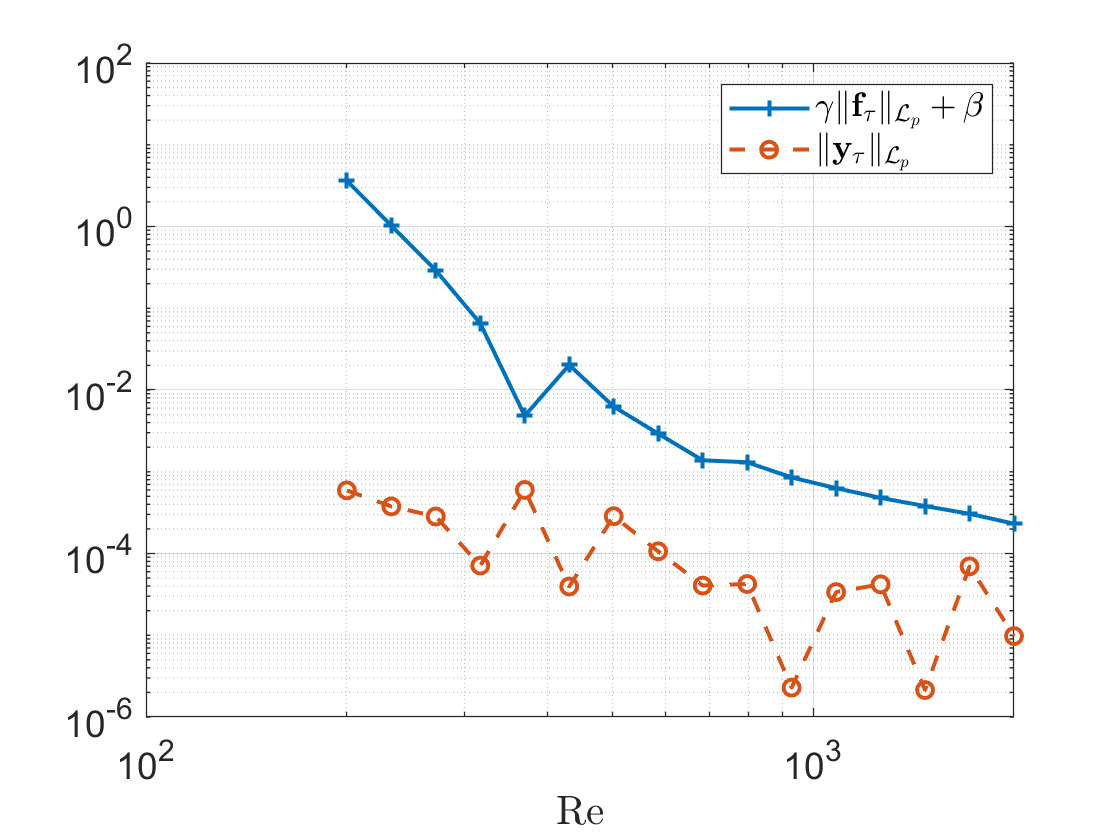



figure;
% loglog(Re_list, u_tau_Lp(:, 1), line_styles{1}, 'LineWidth', line_width, 'Color', colors(1, :));
h1 = loglog(Re_list, Gamma_theorem_max(:,8).*u_tau_Lp(:,8) + beta_theorem_p(:,8), line_styles{1}, 'LineWidth', line_width, 'Color', colors(1, :), 'Marker', markers{1});
hold on;
% h2 = loglog(Re_list, Gamma_theorem_min(:,8).*u_tau_Lp(:,8) + beta_theorem_p(:,8), line_styles{3}, 'LineWidth', line_width, 'Color', colors(3, :), 'Marker', markers{3});
h3 = loglog(Re_list, y_tau_Lp(:, 8), line_styles{2}, 'LineWidth', line_width, 'Color', colors(2, :),'Marker', markers{2});
hold off;
xlim([1e2, 2000]);  
xlabel('Re', 'FontSize', 12, 'Interpreter', 'latex');
legend([h1, h3], {...
    ['$\gamma \|\mathbf{f}_{\tau}\|_{\mathcal{L}_p} + \beta$'], ...
    ['$\|\mathbf{y}_{\tau}\|_{\mathcal{L}_p}$']}, ...
    'Interpreter', 'latex');
grid on;
set(gca, 'FontSize', 14);

hold off;

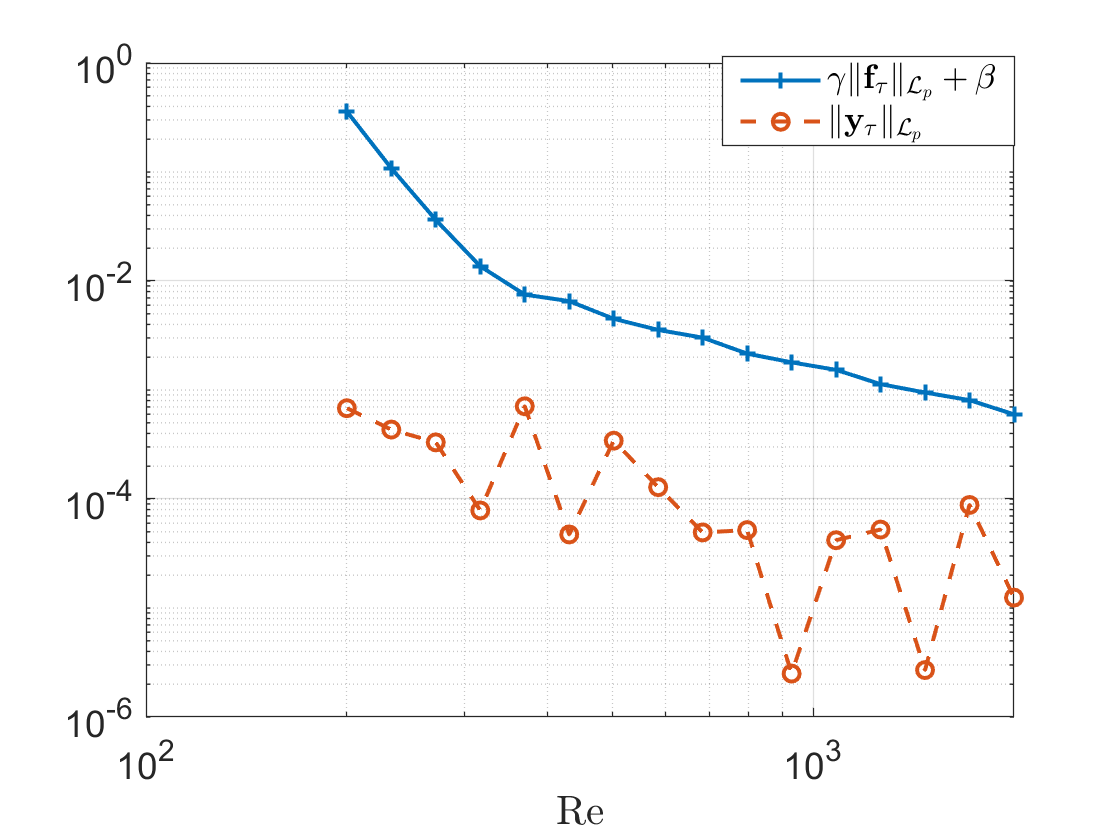


figure;
% loglog(Re_list, u_tau_Lp(:, 1), line_styles{1}, 'LineWidth', line_width, 'Color', colors(1, :));
h1 = loglog(Re_list, Gamma_theorem_max(:,4).*u_tau_Lp(:,4) + beta_theorem_p(:,4), line_styles{1}, 'LineWidth', line_width, 'Color', colors(1, :), 'Marker', markers{1});
hold on;
% h2 = loglog(Re_list, Gamma_theorem_min(:,4).*u_tau_Lp(:,4) + beta_theorem_p(:,4), line_styles{3}, 'LineWidth', line_width, 'Color', colors(3, :), 'Marker', markers{3});
h3 = loglog(Re_list, y_tau_Lp(:, 4), line_styles{2}, 'LineWidth', line_width, 'Color', colors(2, :),'Marker', markers{2});
hold off;
xlim([1e2, 2000]);  
xlabel('Re', 'FontSize', 12, 'Interpreter', 'latex');
legend([h1, h3], {...
    ['$\gamma \|\mathbf{f}_{\tau}\|_{\mathcal{L}_p} + \beta$'], ...
    ['$\|\mathbf{y}_{\tau}\|_{\mathcal{L}_p}$']}, ...
    'Interpreter', 'latex');
grid on;
set(gca, 'FontSize', 14);

hold off;

legend("Position",[0.64503,0.83306,0.26113,0.093])

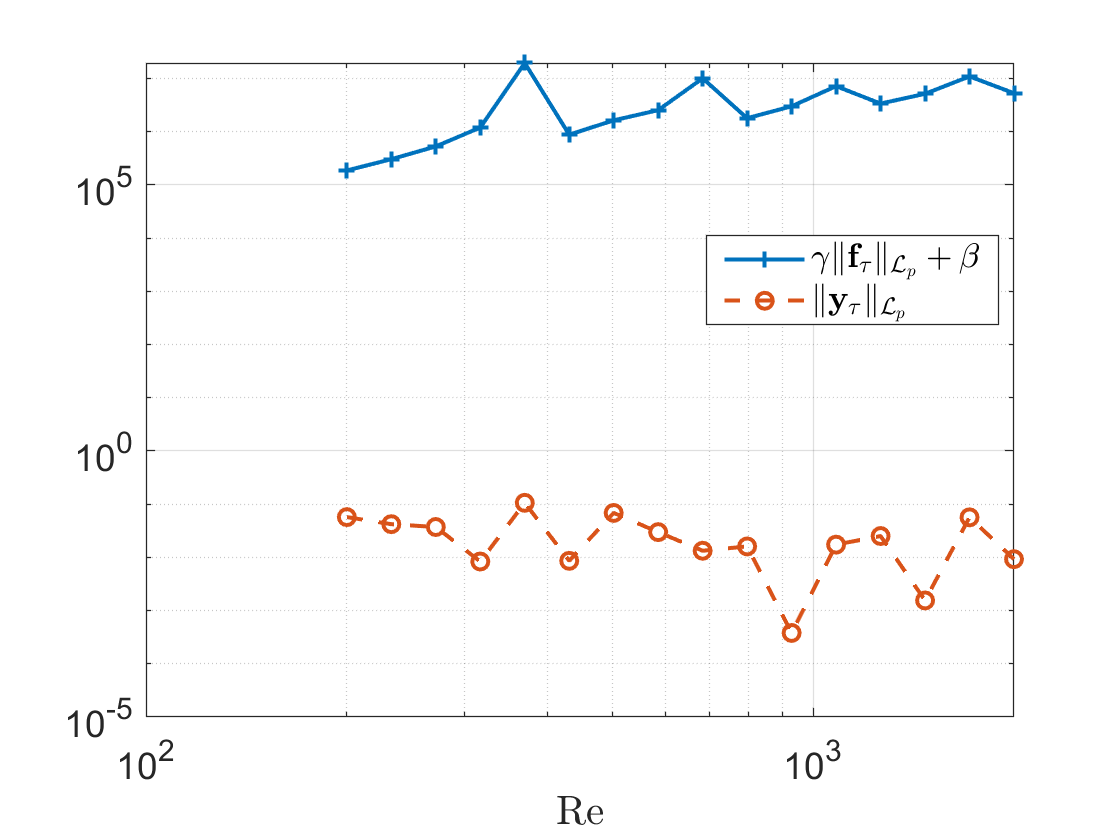


figure;
% loglog(Re_list, u_tau_Lp(:, 1), line_styles{1}, 'LineWidth', line_width, 'Color', colors(1, :));
h1 = loglog(Re_list, Gamma_theorem_max(:,1).*u_tau_Lp(:,1) + beta_theorem_p(:,1), line_styles{1}, 'LineWidth', line_width, 'Color', colors(1, :), 'Marker', markers{1});
hold on;
% h2 = loglog(Re_list, Gamma_theorem_min(:,1).*u_tau_Lp(:,1) + beta_theorem_p(:,1), line_styles{3}, 'LineWidth', line_width, 'Color', colors(3, :), 'Marker', markers{3});
h3 = loglog(Re_list, y_tau_Lp(:, 1), line_styles{2}, 'LineWidth', line_width, 'Color', colors(2, :),'Marker', markers{2});
hold off;
xlim([1e2, 2000]);  
xlabel('Re', 'FontSize', 12, 'Interpreter', 'latex');
legend([h1, h3], {...
    ['$\gamma \|\mathbf{f}_{\tau}\|_{\mathcal{L}_p} + \beta$'], ...
    ['$\|\mathbf{y}_{\tau}\|_{\mathcal{L}_p}$']}, ...
    'Interpreter', 'latex');
grid on;
set(gca, 'FontSize', 14);

hold off;

legend("Position",[0.64503,0.83306,0.26113,0.093])

legend("Position",[0.63052,0.62026,0.26113,0.093])